faceRec = imread('./Face/test.png');

[~, bruh] = system('python ./Face/getFaceCoords.py');
bruh = str2double(regexp(bruh, '\d*', 'Match'))

bruh =     59    87   127   127


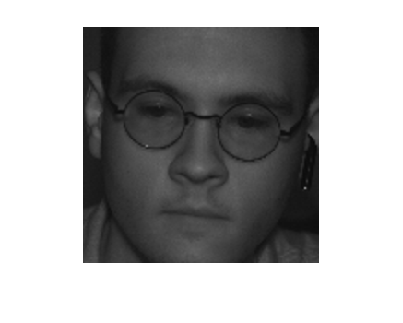

if isempty(bruh)
    quit(1)
end

cx = bruh(1); cy = bruh(2); cw = bruh(3); ch = bruh(4);

faceImg = imresize(faceRec(cy:(cy+ch), cx:(cx+cw)), [256 256]);

imshow(faceImg)


width = 32

width = 32

height = 48

height = 48

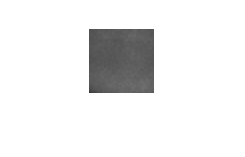


foreImg = faceImg(1:width*2, 128-width:128+width);

imshow(foreImg)